# Hamilton's equations of motion against Descender output

We want to integrate Hamiltonian in two ways:

- Number potential - Euler method

- Stormer-Verlet Symplectic integrator - second order accuracy (later - this actually is not as accurate as it requires finding roots of equations which is not as accurate. Need to implement using vpasolve (MATLAB's symbolic solver))

We will see how H varies with integration, to see stability. It should ideally remain on the H=0 submanifold. On the other hand, if we can get our trajectory to remain on the H=0 submanifold, then the Descender should converge to that - at least locally. 

## Load descender data

load("..\Data\Selkov_descend_1_2straight_3000_31-May-2022.mat")
choose_iter = 580;

load("..\Data\Selkov_descend_1_1straight_3000_31-May-2022.mat")
choose_iter = 499;

load("..\Data\Selkov_descend_1_1straight_4000_08-Jun-2022.mat")
choose_iter = iter;

load('..\Data\Selkov_descend_1_2spiral_4000_10-Jun-2022.mat')
choose_iter = 500;

load("..\Data\Selkov_descend_1_1spiral_4000_10-Jun-2022.mat")
choose_iter = iter;

choose_iter = 30;iter = choose_iter;

PS_traj =  PS_arr(traj_pts*(choose_iter-1)+1:traj_pts*choose_iter,:);

iter = 35;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
S_traj = picker_arr_idx(S_traj_arr,traj_pt_arr,iter);
t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);


traj = PS_traj(:,1:num_spec);
x_targ_start = traj(1,:);
x_targ_end = traj(end,:);
dt = min(diff(t_traj));

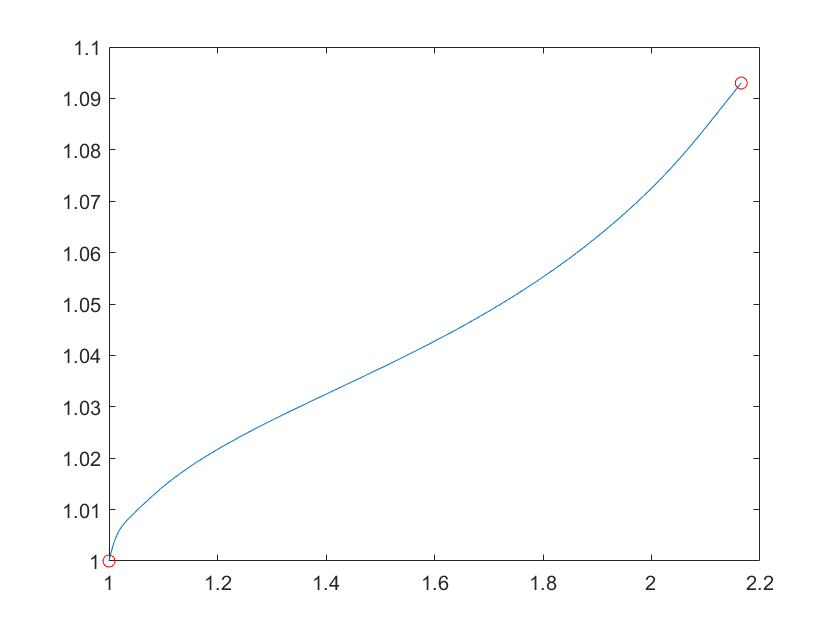


figure()
plot(traj(:,1),traj(:,2:end))
hold on
plot(x_targ_start(:,1),x_targ_start(:,2:end),'ro')
plot(x_targ_end(:,1),x_targ_end(:,2:end),'ro')
hold off


"Action"

ans = "Action"

choose_iter = iter;

S_arr(choose_iter)

ans =    0.016817952447778


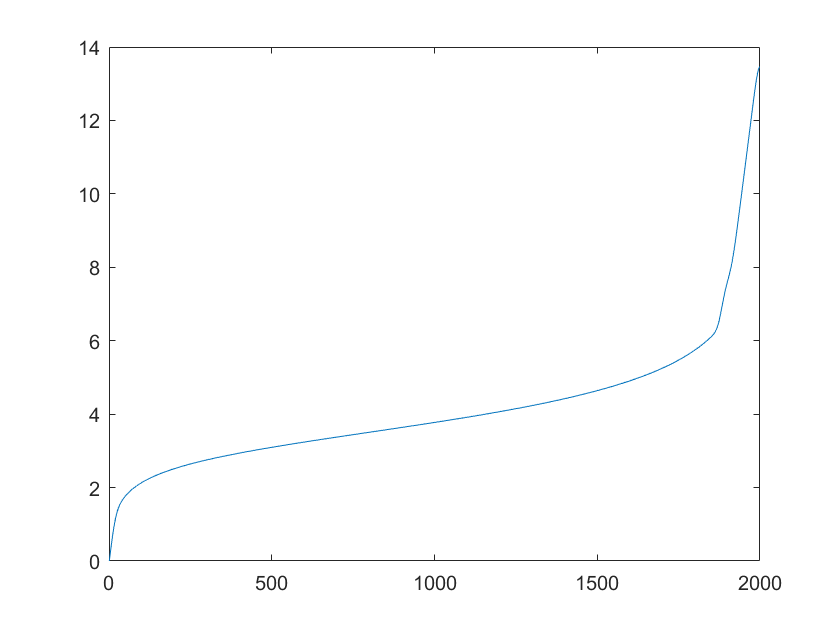

S_traj = picker_arr_idx(S_traj_arr,traj_pt_arr,choose_iter);
t_traj = picker_arr_idx(time_arr,traj_pt_arr,choose_iter);

plot(t_traj)

dt = min(diff(t_traj))

dt =    0.001313235799171


digits 50

size(traj)

ans =    500     2


## Integrate trajectory 

### Explicit Euler in concentration-potential

Start from a single point

pt_idx = 1710;
t_for = 2*(t_traj(end)-t_traj(pt_idx))

t_for =   16.342431629477289


t_back = 2*(t_traj(1)-t_traj(pt_idx))

t_back =  -10.584913969553638


x_ic = PS_traj(pt_idx,:)

x_ic =    1.996915676912154   1.072205921779118   0.004681315980181   0.000270200556943


[Ham_traj_for, t_f, dist_curr_for] = HamEoM_f_Euler(x_ic,x_targ_end,dt,t_for,dHamdq_fun,dHamdp_fun);
t_f = t_f + t_traj(pt_idx);
[Ham_traj_back, t_b, dist_curr_back] = HamEoM_f_Euler(x_ic,x_targ_start,-dt,t_back,dHamdq_fun,dHamdp_fun);
t_b = t_b + t_traj(pt_idx);



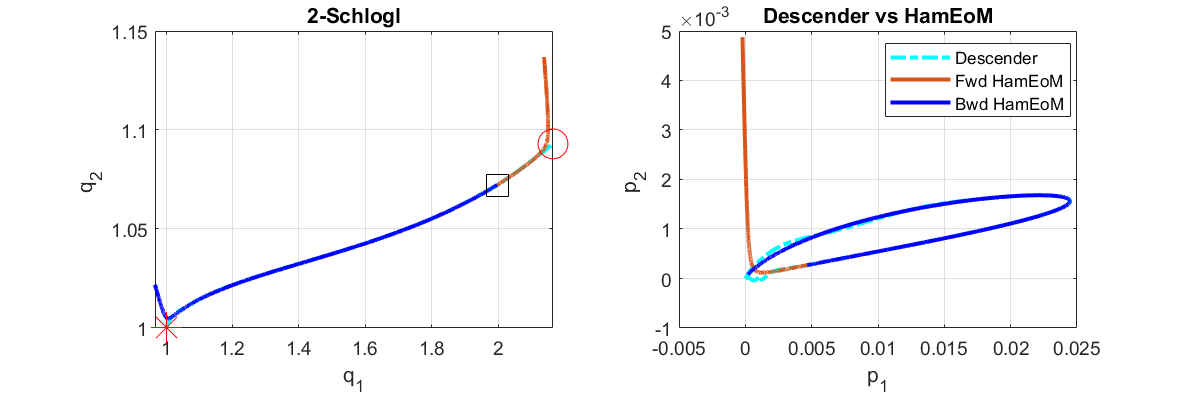

figure()
subplot(1,2,1)
plot(traj(:,1),traj(:,2:end),'c-.','LineWidth',2)
hold on
plot(Ham_traj_for(:,1),Ham_traj_for(:,2:num_spec),'LineWidth',2)
plot(Ham_traj_back(:,1),Ham_traj_back(:,2:num_spec),'b','LineWidth',2)
plot(x_ic(:,1),x_ic(2:num_spec),'ks','MarkerSize',15)
plot(x_targ_start(:,1),x_targ_start(:,2:end),'r*','MarkerSize',15)
plot(x_targ_end(:,1),x_targ_end(:,2:end),'ro','MarkerSize',15)
grid on
hold off
%legend('Descender','Fwd HamEoM','Bwd HamEoM','location','best')
xlabel('q_1')
ylabel('q_2 ')
title(plotnam )

subplot(1,2,2)
plot(PS_traj(:,num_spec + 1),PS_traj(:,num_spec + 2:end),'c-.','LineWidth',2)
hold on
plot(Ham_traj_for(:,num_spec+1),Ham_traj_for(:,num_spec+2:end),'LineWidth',2)
plot(Ham_traj_back(:,num_spec + 1),Ham_traj_back(:,num_spec+2:end),'b','LineWidth',2)
hold off
grid on
legend('Descender','Fwd HamEoM','Bwd HamEoM','location','best')
title('Descender vs HamEoM')
xlabel('p_1')
ylabel('p_2 ')

x0=0.01;
y0=0.01;
width=21;
height=7;
set(gcf,'position',[x0,y0,width,height])
set(gcf,'units','centimeters','position',[x0,y0,width,height])

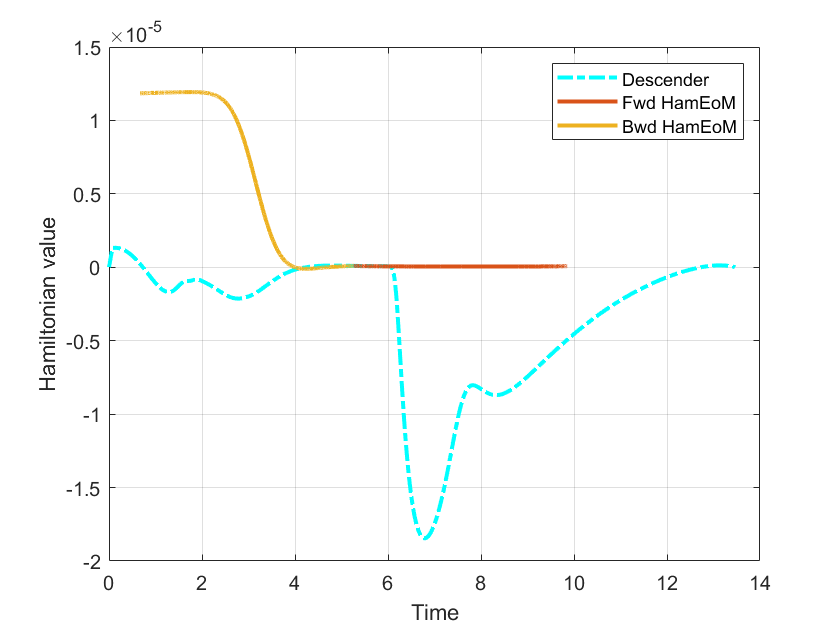

figure()
plot(t_traj,Ham_fun_qp(PS_traj),'c-.','LineWidth',2)
hold on
plot(t_f, Ham_fun_qp(Ham_traj_for),'LineWidth',2)
plot(t_b,Ham_fun_qp(Ham_traj_back),'LineWidth',2)
grid on
hold off
legend('Descender','Fwd HamEoM','Bwd HamEoM')
xlabel('Time')
ylabel('Hamiltonian value')

## Plot againts ES_instanton

load('..\Data\ES_up.mat')
ES_traj = [upp_good_na upp_good_nb];
ES_eta = [upp_good_eta_a,upp_good_eta_b];

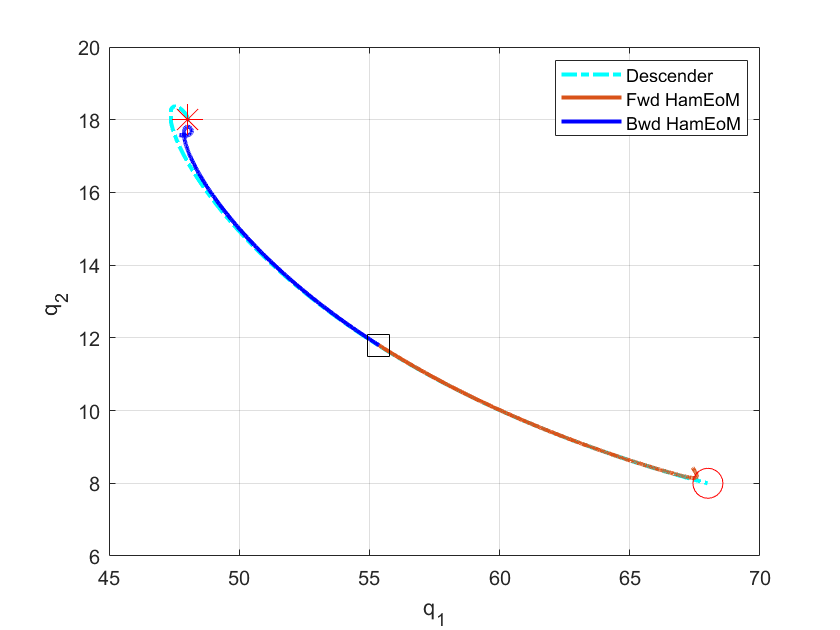

figure()
plot(ES_traj(:,1),ES_traj(:,2:end),'c-.','LineWidth',2)
hold on
plot(Ham_traj_for(:,1),Ham_traj_for(:,2:num_spec),'LineWidth',2)
plot(Ham_traj_back(:,1),Ham_traj_back(:,2:num_spec),'b','LineWidth',2)
plot(x_ic(:,1),x_ic(2:num_spec),'ks','MarkerSize',15)
plot(x_targ_start(:,1),x_targ_start(:,2:end),'r*','MarkerSize',15)
plot(x_targ_end(:,1),x_targ_end(:,2:end),'ro','MarkerSize',15)
grid on
hold off
legend('Instanton','Fwd HamEoM','Bwd HamEoM','location','best')
xlabel('q_1')
ylabel('q_2 ')

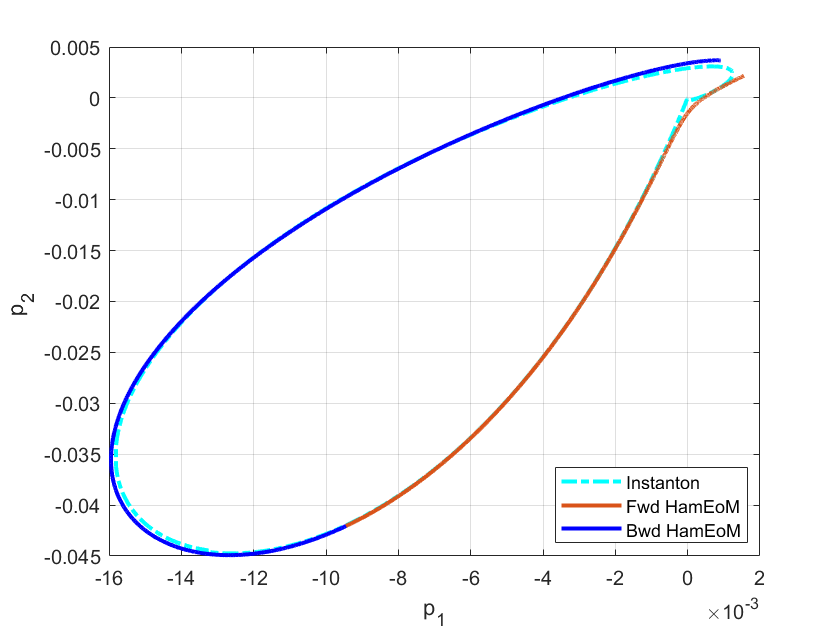

figure()
plot(ES_eta(:,1),ES_eta(:,2:end),'c-.','LineWidth',2)
hold on
plot(Ham_traj_for(:,num_spec+1),Ham_traj_for(:,num_spec+2:end),'LineWidth',2)
plot(Ham_traj_back(:,num_spec + 1),Ham_traj_back(:,num_spec+2:end),'b','LineWidth',2)
hold off
grid on
legend('Instanton','Fwd HamEoM','Bwd HamEoM','location','best')
xlabel('p_1')
ylabel('p_2 ')

## Start from an array of initial conditions

pt_arr = [300:50:1800]

pt_arr =          300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300        1350        1400        1450        1500        1550        1600        1650        1700        1750        1800


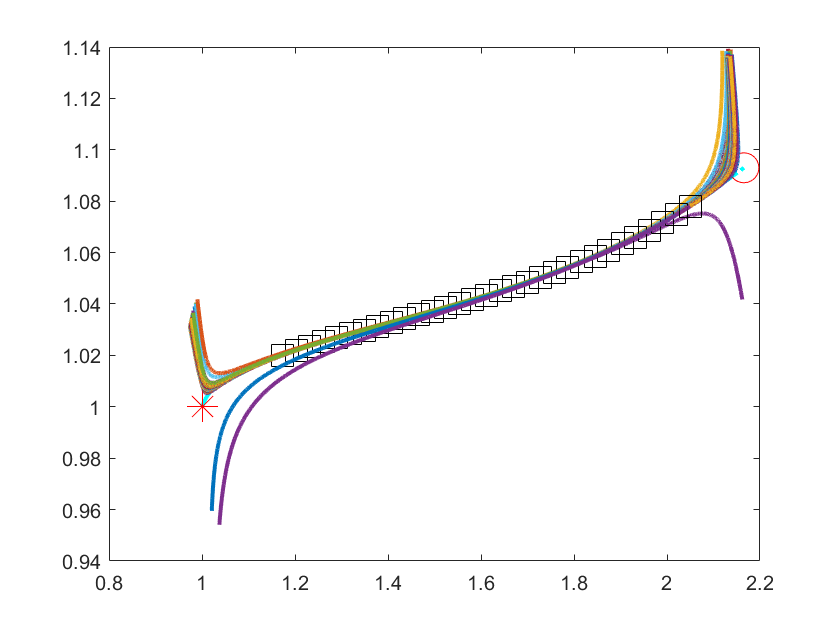

dist_min_arr = zeros(size(pt_arr,2),2);
figure()
plot(traj(:,1),traj(:,2:end),'c-.','LineWidth',2)
hold on
plot(x_targ_start(:,1),x_targ_start(:,2:end),'r*','MarkerSize',15)
plot(x_targ_end(:,1),x_targ_end(:,2:end),'ro','MarkerSize',15)

for i = 1:size(pt_arr,2)
    pt_idx = pt_arr(i);
    t_for = 2*(t_traj(end)-t_traj(pt_idx));
    t_back = 2*(t_traj(1)-t_traj(pt_idx));
    x_ic = PS_traj(pt_idx,:);
    [Ham_traj_for, ~, dist_min_arr(i,1)] = HamEoM_f_Euler(x_ic,x_targ_end,dt,t_for,dHamdq_fun,dHamdp_fun);
    %t_f = t_f + t_traj(pt_idx);
    [Ham_traj_back, ~, dist_min_arr(i,2)] = HamEoM_f_Euler(x_ic,x_targ_start,-dt,t_back,dHamdq_fun,dHamdp_fun);
    %t_b = t_b + t_traj(pt_idx);
    plot(Ham_traj_for(:,1),Ham_traj_for(:,2:num_spec),'LineWidth',2)
    plot(Ham_traj_back(:,1),Ham_traj_back(:,2:num_spec),'LineWidth',2)
    plot(x_ic(:,1),x_ic(2:num_spec),'ks','MarkerSize',15)

end

[a,b] = min(dist_min_arr)

a =     0.0785    0.0561


b =     22     1


pt_arr(4)

ans = 1900

pt_arr(2)

ans = 1700

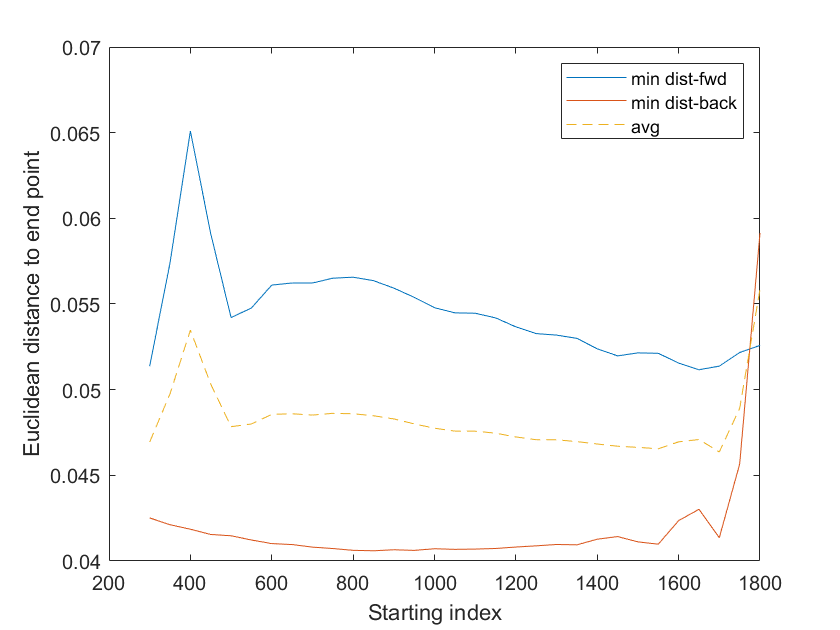

figure()
plot(pt_arr,dist_min_arr(:,1))
hold on
plot(pt_arr,dist_min_arr(:,2))
plot(pt_arr,sum(dist_min_arr,2)./2,'--')
hold off
ylabel('Euclidean distance to end point')
xlabel('Starting index')
legend('min dist-fwd','min dist-back','avg')

[a,b] = min(sum(dist_min_arr,2)./2);
pt_arr(b)

ans =         1700


### Find closest point of approach

pt_arr = [100:100:traj_pts-100];
dist_min_arr = zeros(size(pt_arr,2),2);

for i = 1:size(pt_arr,2)
    pt_idx = pt_arr(i);
    t_for = 2*(t_traj(end)-t_traj(pt_idx));
    t_back = 2*(t_traj(1)-t_traj(pt_idx));
    x_ic = PS_traj(pt_idx,:);
    [Ham_traj_for, ~, dist_min_arr(i,1)] = HamEoM_f_Euler(x_ic,x_targ_end,dt,t_for,dHamdq_fun,dHamdp_fun);
    [Ham_traj_back, ~, dist_min_arr(i,2)] = HamEoM_f_Euler(x_ic,x_targ_start,-dt,t_back,dHamdq_fun,dHamdp_fun);
end
[a,b] = min(sum(dist_min_arr,2)./2);

pt_arr = [pt_arr(b-1):10:pt_arr(b+1)];
dist_min_arr = zeros(size(pt_arr,2),2);

for i = 1:size(pt_arr,2)
    pt_idx = pt_arr(i);
    t_for = 2*(t_traj(end)-t_traj(pt_idx));
    t_back = 2*(t_traj(1)-t_traj(pt_idx));
    x_ic = PS_traj(pt_idx,:);
    [Ham_traj_for, ~, dist_min_arr(i,1)] = HamEoM_f_Euler(x_ic,x_targ_end,dt,t_for,dHamdq_fun,dHamdp_fun);
    [Ham_traj_back, ~, dist_min_arr(i,2)] = HamEoM_f_Euler(x_ic,x_targ_start,-dt,t_back,dHamdq_fun,dHamdp_fun);
end
[a,b] = min(sum(dist_min_arr,2)./2);

pt_idx = pt_arr(b);
t_for = 2*(t_traj(end)-t_traj(pt_idx));

t_for =   16.342431629477289


t_back = 2*(t_traj(1)-t_traj(pt_idx));

t_back =  -10.584913969553638


x_ic = PS_traj(pt_idx,:);

x_ic =    1.996915676912154   1.072205921779118   0.004681315980181   0.000270200556943


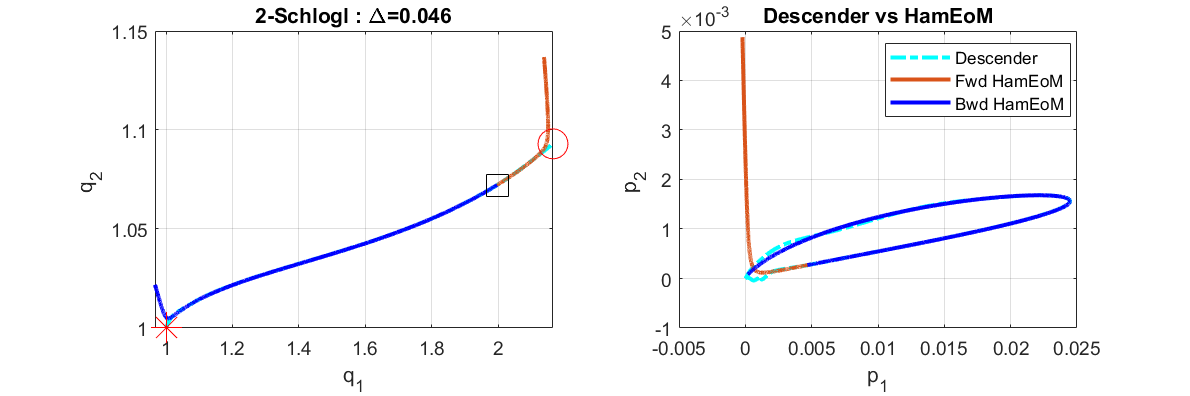

[Ham_traj_for, t_f, dist_curr_for] = HamEoM_f_Euler(x_ic,x_targ_end,dt,t_for,dHamdq_fun,dHamdp_fun);
t_f = t_f + t_traj(pt_idx);
[Ham_traj_back, t_b, dist_curr_back] = HamEoM_f_Euler(x_ic,x_targ_start,-dt,t_back,dHamdq_fun,dHamdp_fun);
t_b = t_b + t_traj(pt_idx);

figure()
subplot(1,2,1)
plot(traj(:,1),traj(:,2:end),'c-.','LineWidth',2)
hold on
plot(Ham_traj_for(:,1),Ham_traj_for(:,2:num_spec),'LineWidth',2)
plot(Ham_traj_back(:,1),Ham_traj_back(:,2:num_spec),'b','LineWidth',2)
plot(x_ic(:,1),x_ic(2:num_spec),'ks','MarkerSize',15)
plot(x_targ_start(:,1),x_targ_start(:,2:end),'r*','MarkerSize',15)
plot(x_targ_end(:,1),x_targ_end(:,2:end),'ro','MarkerSize',15)
grid on
hold off
%legend('Descender','Fwd HamEoM','Bwd HamEoM','location','best')
xlabel('q_1')
ylabel('q_2 ')
title(plotnam +' : \Delta='+string(round(a,3)))

subplot(1,2,2)
plot(PS_traj(:,num_spec + 1),PS_traj(:,num_spec + 2:end),'c-.','LineWidth',2)
hold on
plot(Ham_traj_for(:,num_spec+1),Ham_traj_for(:,num_spec+2:end),'LineWidth',2)
plot(Ham_traj_back(:,num_spec + 1),Ham_traj_back(:,num_spec+2:end),'b','LineWidth',2)
hold off
grid on
legend('Descender','Fwd HamEoM','Bwd HamEoM','location','best')
title('Descender vs HamEoM')
xlabel('p_1')
ylabel('p_2 ')

x0=0.01;
y0=0.01;
width=21;
height=7;
set(gcf,'position',[x0,y0,width,height])
set(gcf,'units','centimeters','position',[x0,y0,width,height])

save_plot_flag = 0;
if save_plot_flag == 1
    saveas(gcf,save_plot_name)
end
save_plot_flag = 0;

## Calculate action

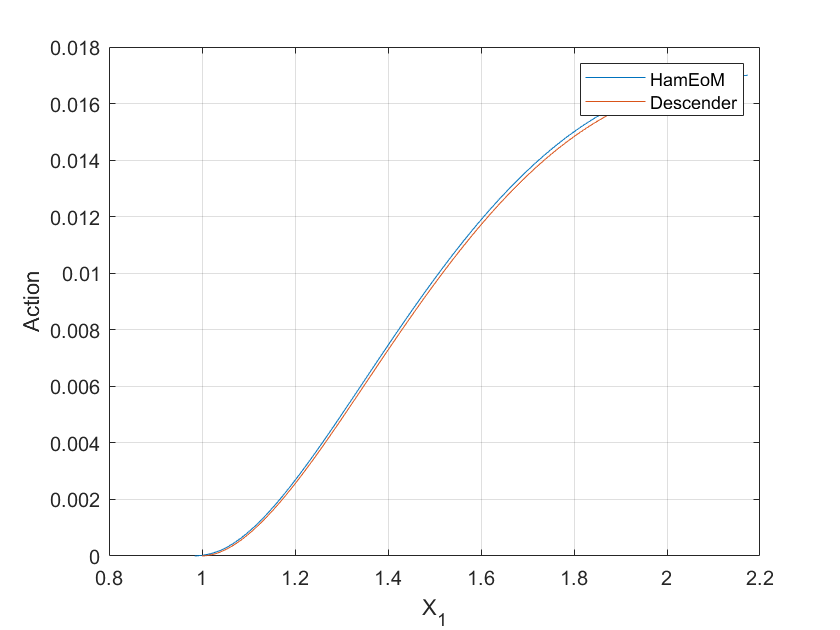

[concat_traj, S_traj_ham] = action_calc(Ham_traj_for,Ham_traj_back);
[a,b] = min(sum(abs(concat_traj(1,1:num_spec)-PS_traj(:,1:num_spec)),2));

figure()
plot(concat_traj(:,1),S_traj_ham+S_traj(b))
hold on
plot(traj(:,1),S_traj)
hold off
grid on
legend('HamEoM','Descender')
xlabel('X_1')
ylabel('Action')

function [concat_traj, S_traj_ham] = action_calc(Ham_PS_traj,Ham_PS_traj_back)
    num_spec = size(Ham_PS_traj,2)/2;

    size_f = size(Ham_PS_traj,1);
    size_b = size(Ham_PS_traj_back,1);
    concat_traj = zeros(size_f + size_b -1,2*num_spec);
    flip_Ham_back = flip(Ham_PS_traj_back);
    concat_traj(1:size_b-1,:) = flip_Ham_back(1:size_b-1,:);
    concat_traj(size_b:size_b+size_f -1,:) = Ham_PS_traj;

    
    %action along trajectory
    S_traj_ham = zeros(size(concat_traj,1),1);
    dS = 0;
    S_0 = 0;
    dq = diff(concat_traj(:,1:num_spec));
    dq = [dq ; zeros(1,num_spec)];
    p_traj = concat_traj(:,num_spec+1:2*num_spec);
    
    for k = 2:size_f+size_b-1
        dS = p_traj(k,:)*dq(k,:).';
        S_traj_ham(k) = S_traj_ham(k-1) + dS ;
    end
    
end
